# Lecture 4: Point Processing Operations

# Part 2: Logarithmic and Gamma Transformations

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture4 - Point Processing

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
clc, clearvars, close all;

I = imread('images/blocks.tif'); %read input image file
if(size(I,3) == 3) % convert to grayscale if not
    I = rgb2gray(I);
end
Id = double(I); %convert to double


## 1. Logarithmic and inverse logarithmic transformation

* Generate transformation functions*

x = 0:255;
c = 255/log(256);
y1 = c*log(x+1);
y2 = exp(x/c)-1;

*Apply log and inverse log transformations on images*

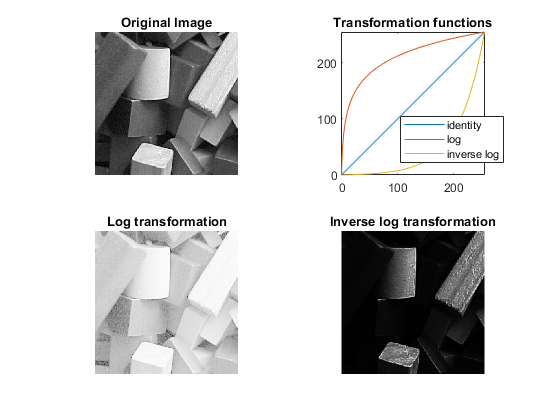

I1 = uint8(c*log(Id+1)); %log transform
I2 = uint8(exp(Id/c)-1); %inverse log transform

% display
figure, subplot(2,2,1), imshow(I), title('Original Image');
subplot(2,2,2), plot(x,x), hold on, plot(x,y1), hold on, plot(x,y2), axis square
axis([0 255 0 255]), title('Transformation functions'), 
legend('identity','log','inverse log','Location','best')
subplot(2,2,3), imshow(I1), title('Log transformation');
subplot(2,2,4), imshow(I2), title('Inverse log transformation');

## 2. Gamma transformation

*Apply transformation functions*

x = 0:255;
gamma1 = 0.4;
gamma2 = 2.5;
y1 = x .^ gamma1;
y2 = x .^ gamma2;
y1 = 255*y1/max(y1);
y2 = 255*y2/max(y2);

*Applying gamma transformation option 1: manual*

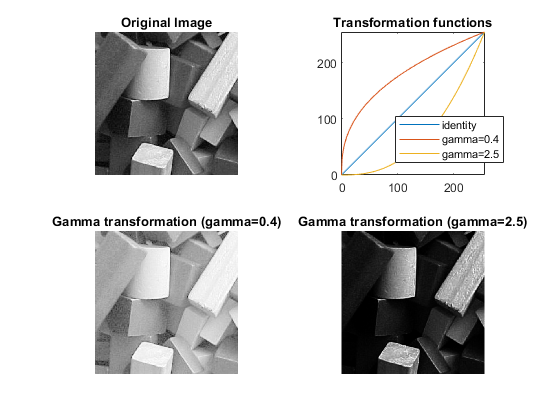

I3 = Id .^ gamma1;
I4 = Id .^ gamma2;

% display
figure,subplot(2,2,1), imshow(I), title('Original Image');
subplot(2,2,2), plot(x,x), hold on, plot(x,y1), hold on, plot(x,y2), axis square 
axis([0 255 0 255]), title('Transformation functions'), 
legend('identity',strcat('gamma= ', num2str(gamma1)),strcat('gamma=', num2str(gamma2)),'Location','best')
subplot(2,2,3), imshow(I3,[]), title(strcat('Gamma transformation (gamma=', num2str(gamma1), ')'));
subplot(2,2,4), imshow(I4,[]), title(strcat('Gamma transformation (gamma=', num2str(gamma2), ')'));

*Applying gamma transformation option 2: using imadjust function*

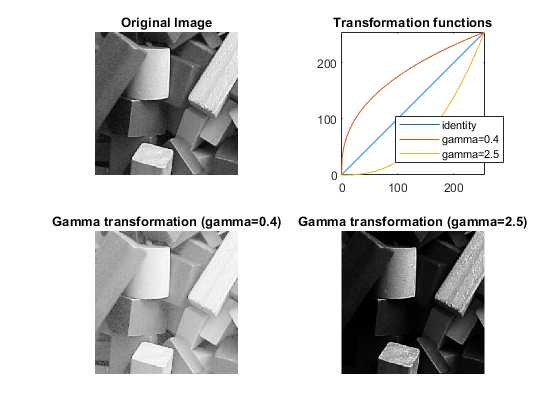

I5 = imadjust(I,[],[],gamma1);
I6 = imadjust(I,[],[],gamma2);

figure, subplot(2,2,1), imshow(I), title('Original Image');
subplot(2,2,2), plot(x,x), hold on, plot(x,y1), hold on, plot(x,y2), axis square 
axis([0 255 0 255]), title('Transformation functions'), 
legend('identity',strcat('gamma= ', num2str(gamma1)),strcat('gamma=', num2str(gamma2)),'Location','best')
subplot(2,2,3), imshow(I5), title(strcat('Gamma transformation (gamma=', num2str(gamma1), ')'));
subplot(2,2,4), imshow(I6), title(strcat('Gamma transformation (gamma=', num2str(gamma2), ')'));